# Demonstrate order sorting

oRow = 3; % Row order. Number of rows is 2^oRow
oCol = 3; % Column order. Number of columns is 2^oRow
N = 2^(oRow+oCol); % number of patterns
nRow = 2^oRow;
nCol = 2^oCol;

H = hadamard(N); 

% Hadamard ordering
figure();
title("A set of 2D Hadamard patterns in natural order");
colormap("gray");
for i = 1:N 
    subplot(nCol,nRow,i); 
    imagesc(reshape(H(:,i),nRow,nCol));
    axis equal;
    xticks([]);
    yticks([]);
    title(i-1);
end

% Sorted ordering
figure();
title("The same 2D Hadamard patterns sorted by resolution order");
colormap("gray");
ix = 0:N-1;
iy = oderedIndex2HadamardIndex(ix, oRow, oCol);
for i = 1:N 
    subplot(nCol,nRow,i); 
    imagesc(reshape(H(:,iy(i)+1),nRow,nCol));
    axis equal;
    xticks([]);
    yticks([]);
    title(iy(i));
end


## Image sampling and reconstruction demo

This example loads a "ground truth" image and simulates the measurement using Hadamard sampling. Perfect sampling is assumed. For each pattern in the sequence, the partially acuired image is reconstructed and compared to the ground truth to generate an image RMSE.

(Splitting the Hadamard patterns to H+, H- pairs is not explicitly included here because it has no effect if perfect sampling is assumed.)

% load a reference image
oRow = 8; 
oCol = 8;
N = 2^(oRow+oCol); % number of patterns
nRow = 2^oRow;
nCol = 2^oCol;

ref = imread("James_Blakesley_2017_.jpg");
ref = imresize(ref, [nRow,nCol]);
ref = im2gray(ref);
ref = double(reshape(ref,numel(ref),1)); % Reshape image into vector form

% Perform simulated sampling
ix = 0:N-1;
iHadamard = oderedIndex2HadamardIndex(ix, oRow, oCol) + 1; % Pattern indices in sorted order
iRandom = randperm(numel(iHadamard)); % Pattern indices in random sampling order
iMeas = fastHadamardTransform(ref); % Simulates the measurement of each pattern by performing forward Hadamard transform
iMeasSorted = iMeas(iHadamard);
imRecRas = zeros(size(iMeas));

figure();
colormap("gray");
tiledlayout('flow');
for i = 1:N % For each pattern in the sequence, reconstruct the partially acquired image so far

    % reconstruct with raster and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(1:i) = iMeas(1:i);
    imRecRas(i) = ref(i);
    RMSERas(i) = sqrt(sum((ref-imRecRas).^2));

    % reconstruct with sorted patterns and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(iHadamard(1:i)) = iMeasSorted(1:i);
    imRecOrdered = fastHadamardTransform(partSignal)/N; % reconstruct by inverse Hadamard transform
    RMSEOrdered(i) = sqrt(sum((ref-imRecOrdered).^2));
    if mod(log2(i),1) == 0
        nexttile();
        image(reshape(imRecOrdered,nRow,nCol));
        xticks([]);
        yticks([]);
        title(i);
    end

    % reconstruct with Hadamard ordered patterns and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(1:i) = iMeas(1:i);
    imRecHad = fastHadamardTransform(partSignal)/N;
    RMSEHad(i) = sqrt(sum((ref-imRecHad).^2));

    % reconstruct with Random ordered patterns and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(iRandom(1:i)) = iMeas(iRandom(1:i));
    imRecRand = fastHadamardTransform(partSignal)/N;
    RMSERand(i) = sqrt(sum((ref-imRecRand).^2));
end
figure;
plot([RMSEOrdered;RMSEHad;RMSERand;RMSERas]');
ylabel("RMSE");
legend(["Ordered","Hadamard sequence","Random","Raster"]);



## Reconstruct from real measurements

This example performs partial reconstructions from real measurement data acquired using our system. The image is reconstructed for each measurement from 0 % to 100 % sampling ratio and RMSE is calculated compared to the 100 % recosntructed image.

% load from example test data
filename = ".\Example data\CIGS 2048x1024.txt";
oRow = 10; 
oCol = 11;
N = 2^(oRow+oCol); % number of patterns
nRow = 2^oRow;
nCol = 2^oCol;
cropArea = 10; % top left pixels are zeroed to remove Hadamard artefact

measurements = readData(filename);
measurements = table2array(measurements);

% separate the positive and negative split Hadamard measurements
iPos = measurements(measurements(:,1)>0,:);
iNeg = measurements(measurements(:,1)<0,:);

% sort and sum the positive and negative signals
iMeas = accumarray(iPos(:,1),iPos(:,2),[],@mean);
iMeas = iMeas - accumarray(-iNeg(:,1),iNeg(:,2),[],@mean);

% add in the zero index: (This assumes that the first two elements are the zero
% index elements).
iMeasSorted = [(measurements(1,1)-measurements(1,2)),iMeas'];
if numel(iMeasSorted)<N 
    iMeasSorted(N) = 0; % fill with zeros if not all indexes are measured.
end
ix = 0:N-1;
iy = oderedIndex2HadamardIndex(ix, oRow, oCol) +1;
iMeas(iy) = iMeasSorted;

% Reconstruct the complete image
ref = fastHadamardTransform(iMeas);

% Generate a mask for zeroing outside area
% This is needed because Hadamard atefacts are generated in the top-left
% corner that spoil the image. This feature has been removed more recently
% by randomising the order of H+ and H- patterns. 
maskIndex = zeros(nRow,nCol);
maskIndex(1:cropArea,:) = 1;
maskIndex(:,1:cropArea) = 1;
maskIndex = reshape(maskIndex,size(ref));
maskValue = 0;
ref(maskIndex==1) = maskValue;

% Illustrate the reconstruction
figure();
colormap("gray");
tiledlayout('flow');

samples = ceil(linspace(1,N,1000));
samples = unique([samples, 2.^(1:oRow+oCol)]);
RMSEOrdered = zeros(size(samples));

for i = 1:numel(samples)
    % reconstruct with sorted patterns and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(iy(1:samples(i))) = iMeasSorted(1:samples(i));
    imRecOrdered = fastHadamardTransform(partSignal);
    imRecOrdered(maskIndex==1) = maskValue;
    RMSEOrdered(i) = sqrt(sum((ref-imRecOrdered).^2));
    if i>1 && floor(log2(samples(i)))>floor(log2(samples(i-1)))
        nexttile();
        imagesc(reshape(imRecOrdered,nRow,nCol));
        xticks([]);
        yticks([]);
        title(samples(i));
    end
end

figure;
plot(samples/N,RMSEOrdered);
ylabel("RMSE");
xlabel("Sample ratio");
legend(["Ordered"]);


### Simulating basic noise

This time we add the split Hadamard formalism. 

A pseudoinverse based method is included as an alternative to the Hadamard inversion method. This makes better use of all of the measurement data to reduce noise. In the absence of noise the result is identical.

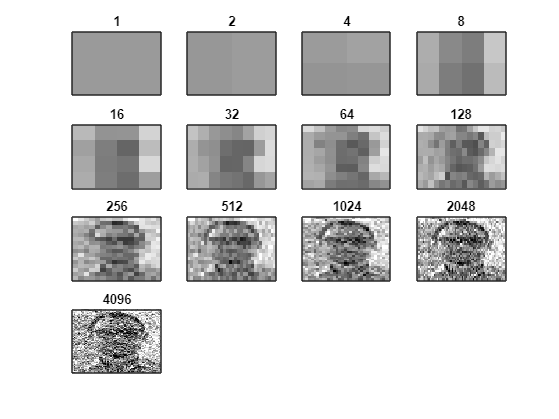

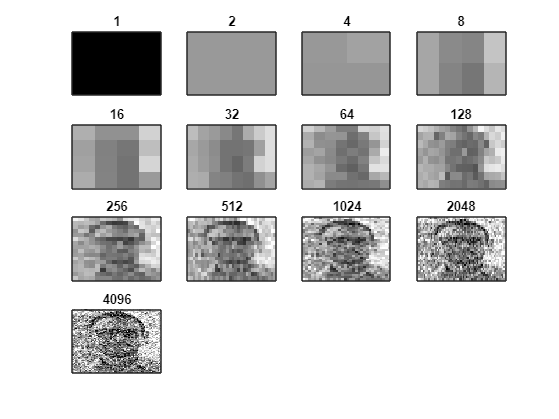

clear;

% load a reference image
oRow = 6; 
oCol = 6;
N = 2^(oRow+oCol); % number of patterns
nRow = 2^oRow;
nCol = 2^oCol;
noise = 10*256; % RMS noise amplitude

ref = imread("James_Blakesley_2017_.jpg");
ref = imresize(ref, [nRow,nCol]);
ref = im2gray(ref);
ref = double(reshape(ref,numel(ref),1)); % Reshape image into vector form

% Perform simulated sampling with split Hadamard and noise
ix = 0:N-1;
iHadamard = oderedIndex2HadamardIndex(ix, oRow, oCol) + 1; % Pattern indices in sorted order
iRandom = randperm(numel(iHadamard)); % Pattern indices in random sampling order
[iMeasHPlus, iMeasHMinus, yFull, HFull] = measureSplitHadamardTransform(ref); % Simulates the measurement of each pattern by performing forward Hadamard transform
iMeasHPlus = iMeasHPlus + normrnd(0, noise, size(ref));
iMeasHMinus = iMeasHMinus + normrnd(0, noise, size(ref));
iMeas = iMeasHPlus - iMeasHMinus;
yFull = yFull + normrnd(0, noise, size(yFull));
iMeasSorted = iMeas(iHadamard);
yFullSorted = yFull;
yFullSorted(1:2:end) = yFull(iHadamard*2-1);
yFullSorted(2:2:end) = yFull(iHadamard*2);
HFullSorted = HFull;
HFullSorted(1:2:end,:) = HFull(iHadamard*2-1,:);
HFullSorted(2:2:end,:) = HFull(iHadamard*2,:);


f1 = figure();
colormap("gray");
tiledlayout('flow');

f2 = figure();
colormap("gray");
tiledlayout('flow');

for i = 1:N % For each pattern in the sequence, reconstruct the partially acquired image so far

    % reconstruct with sorted patterns and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(iHadamard(1:i)) = iMeasSorted(1:i);
    imRecOrdered = fastHadamardTransform(partSignal)/N; % reconstruct by inverse Hadamard transform
    RMSEOrdered(i) = sqrt(sum((ref-imRecOrdered).^2)/N);
    BiasOrdered(i) = abs(sum(ref-imRecOrdered)/N);

    % reconstruct using full matrix pseudoinvers and measure image RMSE
    % reconstruction is row by row
    if i<=1
        imRecFull = zeros(size(ref));
        imRecFullSum = 0;
        imRecFullDiff = imRecFull;
    else
        % reconstruct next row of measurement matrix.
        imRecFullSum = imRecFullSum + (yFullSorted(i*2-1) + yFullSorted(i*2))/N;
        imRecFullDiff = imRecFullDiff + yFullSorted(i*2-1)*(HFullSorted(i*2-1,:)'-HFullSorted(i*2,:)')/N;
        imRecFullDiff = imRecFullDiff + yFullSorted(i*2)*(HFullSorted(i*2,:)'-HFullSorted(i*2-1,:)')/N;
        imRecFull = imRecFullSum/(i-1) + imRecFullDiff*(i-2)/(i-1);
    end
    RMSEFull(i) = sqrt(sum((ref-imRecFull).^2)/N);
    BiasFull(i) = abs(sum(ref-imRecFull)/N);

    % reconstruct with Random ordered patterns and measure image RMSE
    partSignal = zeros(size(iMeas));
    partSignal(iRandom(1:i)) = iMeas(iRandom(1:i));
    imRecRand = fastHadamardTransform(partSignal)/N;
    RMSERand(i) = sqrt(sum((ref-imRecRand).^2)/N);
    BiasRand(i) = abs(sum(ref-imRecRand)/N);

    % plotting
    if mod(log2(i),1) == 0
        figure(f1);
        nexttile();
        image(reshape(imRecOrdered,nRow,nCol));
        xticks([]);
        yticks([]);
        title(i);

        figure(f2);
        nexttile();
        image(reshape(imRecFull,nRow,nCol));
        xticks([]);
        yticks([]);
        title(i);
    end
end

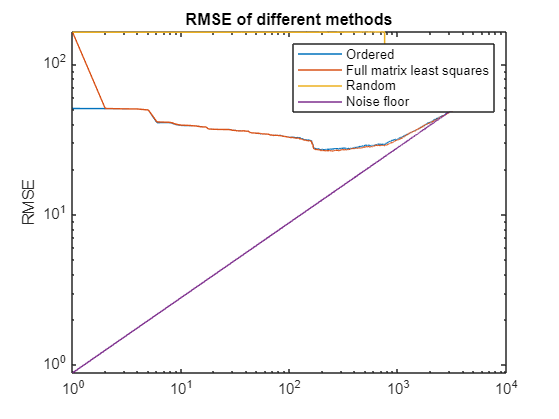

NoiseFloor = noise*sqrt((1:N)*2)/N;

figure;
loglog([RMSEOrdered;RMSEFull; RMSERand; NoiseFloor]');
ylabel("RMSE");
legend(["Ordered","Full matrix least squares","Random","Noise floor"]);
title("RMSE of different methods");

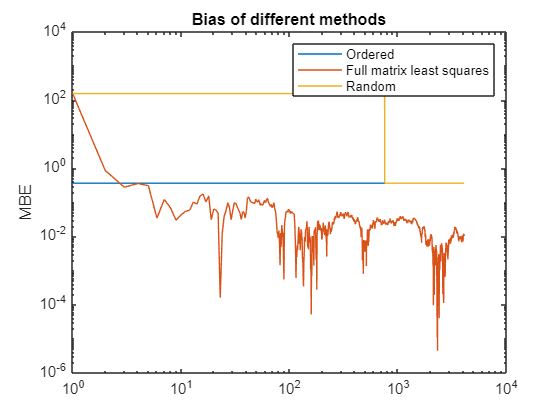


figure;
loglog([BiasOrdered;BiasFull; BiasRand]');
ylabel("MBE");
legend(["Ordered","Full matrix least squares","Random"]);
title("Bias of different methods");

## Functions

function iy = oderedIndex2HadamardIndex(ix, oCol, oRow)
% Converts from ordered indices to Hadamard indices, where ix are indices for sorted 2D Hadamard
% patterns of 2^oRow x 2^oCol pixels and iy are the corresponding Hadamard
% ordered indices

bitSwapOrder = 1:oCol+oRow;
bitSwapOrder = flip(bitSwapOrder);
i1 = 2*min(oCol,oRow);
b1 = bitSwapOrder(1:i1);
b2 = bitSwapOrder(i1+1:end);
b11 = b1(1:2:end);
b12 = b1(2:2:end);
b11 = [b11,b2];
b12 = [b12,b2];
bitSwapOrder = [b11(1:oRow),b12(1:oCol)];

a = dec2bin(ix);
b = a(:,bitSwapOrder);
iy = bin2dec(b);
end

function y = fastHadamardTransform(x)
    % Performs a fast Hadamard transform on x, returning y = H*x.

    % Ensure the input length is a power of 2
    n = length(x);
    if mod(log2(n), 1) ~= 0
        error('Input length must be a power of 2.');
    end
    
    % Perform the Fast Hadamard Transform
    y = x;
    for step = 1:log2(n)
        half = 2^(step - 1);
        for i = 1:half*2:n
            for j = 0:half-1
                a = y(i + j);
                b = y(i + j + half);
                y(i + j) = a + b;
                y(i + j + half) = a - b;
            end
        end
    end
end

function [yPlus, yMinus, yFull, HFull] = measureSplitHadamardTransform(x)
    % Calculates the split Hadamard sampling of x. The Hadamard matrix is
    % split into a positive part (where 0 replaces -1) and a negative part
    % (where +1 becomes 0 and -1 becomes +1). These are then each multiplied by
    % the signal x to give yPlus and yMinus respectively.
    % If yFull and HFull are included as output arguments then the full
    % measurement matrix and full set of measurements are returned.

    % Ensure the input length is a power of 2
    n = length(x);
    if mod(log2(n), 1) ~= 0
        error('Input length must be a power of 2.');
    end
    
    yPlus = x;
    yMinus = x;
    if nargout>3
        yFull = [x;x];
        HFull = zeros(numel(x)*2,numel(x));
    end

    x_i0 = zeros(size(x));
    for i = 1:numel(x)
        % get the Hadamard matrix row for element i
        x_i = x_i0;
        x_i(i) = 1;
        Hrow = fastHadamardTransform(x_i)';
        % get the H+ part of the pattern for the ith measurement
        Hrow(Hrow<0) = 0;
        yPlus(i) = Hrow*x;
        % get the H- part of the parrern for the ith measurement
        Hrow = 1-Hrow;
        yMinus(i) = Hrow*x;
        if nargout>3
            yFull(i*2-1) = yPlus(i);
            yFull(i*2) = yMinus(i);
            HFull(i*2-1,:) = 1-Hrow;
            HFull(i*2,:) = Hrow;
        end
    end

end

function measurements = readData(filename)
    
    % Set up the Import Options and import the data
    opts = delimitedTextImportOptions("NumVariables", 2);
    
    % Specify range and delimiter
    opts.DataLines = [4, Inf];
    opts.Delimiter = "\t";
    
    % Specify column names and types
    opts.VariableNames = ["PatternIndex", "MeasuredCurrentA"];
    opts.VariableTypes = ["double", "double"];
    
    % Specify file level properties
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";
    
    % Import the data
    measurements = readtable(filename, opts);

end
